% Author: Gerardo Parra
clear

# Plot Traces from Task

% input information for finding data
data_path = fullfile( 'Z:','Groups','SPA','01_Data_Raw_Summary_Processed', ...
                      'EEG','Participant_Data','03_Processed_Data','01_In_Progress' );
task      = '08_Random_Loudness_v2';
beapp_tag = '_seg_pt1_30';
fig_path = fullfile(data_path,task,'figures','traces_by_group');

% input channel(s) and other parameters to create plot
chan_1020    = {'C3'};
chan_other   = [ ]; %30 41
chan_weights = [ ];
exclude      = {''};  % ids of subjects to exclude
trial_thresh = 10;
save_fig     = false;
use_happe    = false;
plot_indivs  = true;
use_median   = false;  % use median (rather than mean) to create plot
norm_data    = false;  % normalize subject data before averaging
norm_type    = 'medianiqr';  % type of normalization to use (see matlab 'normalize')

% input time range and other parameters for plot format
conds_to_plot = 1:4;
cond_names    = {'Index','Middle','Both'};
%cond_names = {'30dB','40dB','50dB','60dB','70dB','70dB','60dB','50dB','40dB','30dB','20dB','10dB','0dB'};
cond_names = {'D150', 'D160', 'D170', 'D180'};% (dB level is last 2 digits)

group_names   = {'all'};%'TD','ASD','SPD'};
% colors        = {[0 0 0],[0.35 0.35 0.35],[0.7 0.7 0.7]};
colors        = {[0 0.4470 0.7410],[0.8500 0.3250 0.0980],[0.9290 0.6940 0.1250],[0.7 0.7 0.7]};
colors        = flip(colors);
time_range    = [-100 500];  % time range to show on plot
times_to_plot = [-100:50:500];  % times to label on plot
fig_size      = [150 150 800 350];  % [x y width height]
ylims   = [-10 10];
x_label = 'Time (ms)';
y_label = 'Amplitude (\muV)';

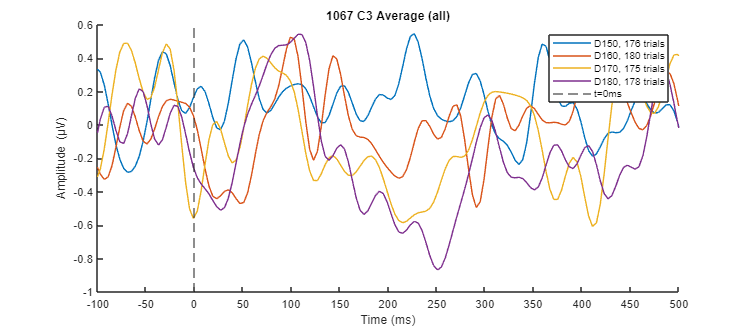

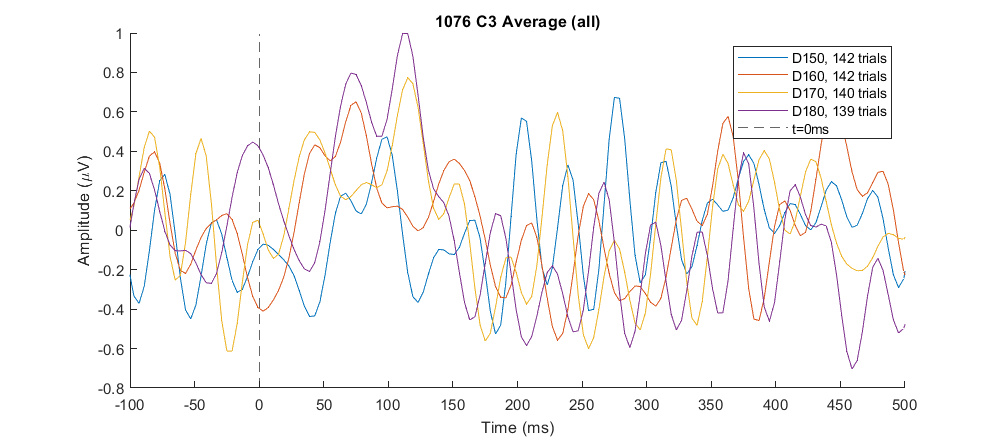

% get paths for loading data
grp_label_path = fullfile(data_path,'01_Subject_Info_for_Processing','same_group.mat');
gpi_path = ['out' beapp_tag filesep 'Run_Report_Variables_and_Settings' ...
                                     beapp_tag '.mat'];
load([data_path filesep task filesep gpi_path])
gpi = grp_proc_info;
clear grp_proc_info

% load group information
load(grp_label_path,'groups')
ids = setdiff(groups.id,exclude);

% get segmentation window
seg_win = [gpi.evt_seg_win_start gpi.evt_seg_win_end] * 1000;
n_samples = ceil(250 * sum(abs(seg_win))/1000);

% generate times for x-axis
times = round(linspace(seg_win(1),seg_win(2),n_samples));
%times = unique(get_indexes(times,[time_range(1):time_range(2)]))
% load and plot data
if use_happe; seg_folder = 'HAPPE_V3'; else seg_folder = 'segment'; end
data_dir = dir(fullfile(data_path,task,[seg_folder beapp_tag],'*.mat'));
n_files = size(data_dir,1);
conds_i = 1:length(conds_to_plot);
grand_avg = cell(length(conds_to_plot),length(group_names));
for i_f = 1:n_files
    file = data_dir(i_f);
    load([file.folder filesep file.name],'eeg_w')
    chan_str = get_chan_str(chan_1020,chan_other);
    
    % get subject group
    subject  = file.name(1:4);
    s_idx  = strcmp(groups.id,subject);
    grp_id = groups.group(s_idx);
    min_trials = min(cellfun('size',eeg_w,3));
    if isempty(grp_id) || sum(strcmp(exclude,subject)) > 0 || min_trials < trial_thresh
        continue
    end
    
    trace = trace_to_matrix(eeg_w, chan_1020, chan_other, chan_weights, use_median);
    if max(trace,[],'all') < 1e-6, continue; end
    if norm_data
        trace = normalize(trace',norm_type)';
    end

    if plot_indivs
        titl = plaintext([subject ' ' chan_str ' Average (' group_names{grp_id} ')']) ;
        prep_fig(fig_size,titl,x_label,y_label,times_to_plot,time_range);
        for i_c  = conds_i
            n_trials = size(eeg_w{i_c},3);
            plot(times,trace(conds_to_plot(i_c),:),'DisplayName',[cond_names{i_c} ', ' int2str(n_trials) ' trials'])
        end
        xline(0,'--','DisplayName','t=0ms');
    end
    
    % save traces of selected loudnesses/conditions
    for i_c = conds_i
        grand_avg{i_c,grp_id}(end+1,:) = trace(conds_to_plot(i_c),:);
    end
end


chan_str = get_chan_str(chan_1020,chan_other);
if norm_data
    ylims = [-2 2];
    beapp_tag = [beapp_tag '_norm'];
end

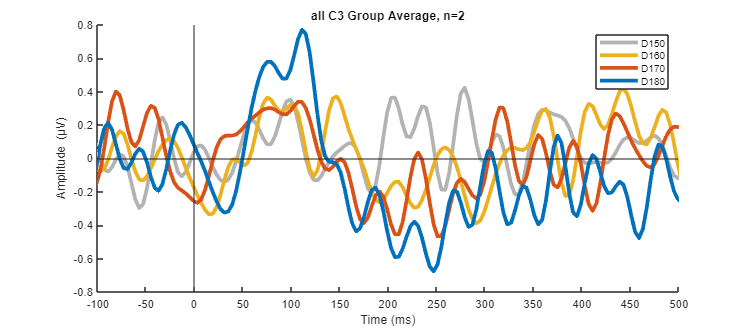

Index in position 2 exceeds array bounds. Index must not exceed 1.

% generate times for x-axis
for i_g = 1:3
    n_subjs = size(grand_avg{1,i_g},1);
    group = group_names{i_g};

    if norm_data
        titl = [group ' ' chan_str ' Group Average - Normalized, n=' int2str(n_subjs)];
    else
        titl = [group ' ' chan_str ' Group Average, n=' int2str(n_subjs)];
    end
    f = prep_fig(fig_size,titl,x_label,y_label,times_to_plot,time_range);
    for i_c = conds_i
        % calculate group mean and SE
        grp_data = grand_avg{i_c,i_g};
        grp_mean = squeeze(mean(grp_data,1,'omitnan'));
        grp_SE   = std(grp_data,0,1,'omitnan')/sqrt(n_subjs);
        
        % get & plot confidence intervals
%         xconf = [times times(end:-1:1)];
%         yconf = [grp_mean+grp_SE grp_mean(end:-1:1)-grp_SE(end:-1:1)];
%         ci = fill(xconf,yconf,colors{i_c},'FaceAlpha',0.3);
        ci.EdgeColor = 'none';

        % plot average
        plot(times,grp_mean,'linewidth',3,'color',colors{i_c})
    end
    xline(0,'DisplayName','t = 0 ms');
    yline(0,'DisplayName','y = 0 \muV');
  %  ylim([-1 1])
    
    % generate legend
    legend_names = {};
    for i_c = conds_to_plot
       % legend_names{end+1} = '';
        legend_names{end+1} = cond_names{i_c};
    end
    legend(legend_names)
    
    if save_fig
        if ~exist(fig_path)
            mkdir(fig_path)
        end
        fig_fname = [group '_' chan_str beapp_tag '_' get_date_str()];
        saveas(f,fullfile(fig_path,fig_fname),'jpg')
    end
end

function f = prep_fig(fig_size,titl,x_lab,y_lab,x_ticks,x_lim)
    % create_figure
    f = figure('Position',fig_size);
    hold on
    legend show
    title(titl)
    xlabel(x_lab)
    ylabel(y_lab)
    
    % adjust x-axis
    xticks(x_ticks)
    xlim(x_lim)
end